clc
close all
clear 

## Input

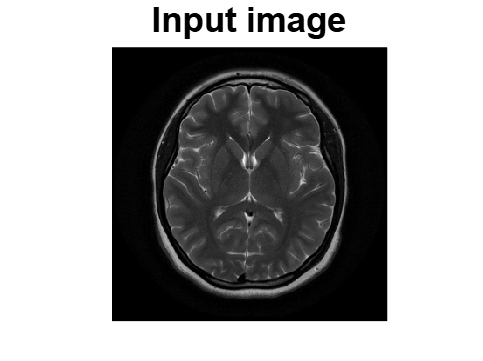

[I,path]=uigetfile('*.jpg','select a input image');
str=strcat(path,I);
s=imread(str);
figure;
imshow(s);
title('Input image','FontSize',20);

## filter

num_iter = 10;
delta_t = 1/7;
kappa = 15;
option = 2;
disp('Preprocessing image please wait . . .');

Preprocessing image please wait . . .


inp = anisodiff(s,num_iter,delta_t,kappa,option);

Removing noise
Filtering Completed !!

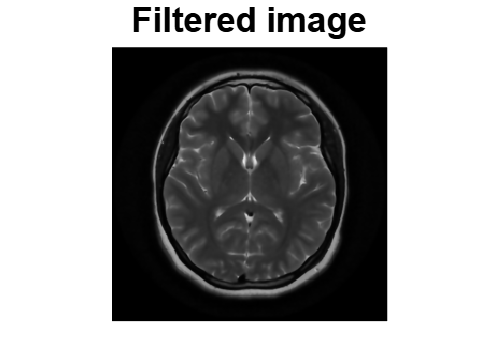

inp = uint8(inp);

inp=imresize(inp,[256,256]);
if size(inp,3)>1
    inp=rgb2gray(inp);
end
figure;
imshow(inp);
title('Filtered image','FontSize',20);



sout=imresize(inp,[256,256]);
t0=60;
th=t0+((max(inp(:))+min(inp(:)))./2);
for i=1:1:size(inp,1)
    for j=1:1:size(inp,2)
        if inp(i,j)>th
            sout(i,j)=1;
        else
            sout(i,j)=0;
        end
    end
end
label=bwlabel(sout);
stats=regionprops(logical(sout),'Solidity','Area','BoundingBox');
density=[stats.Solidity];
area=[stats.Area];
high_dense_area=density>0.6;
max_area=max(area(high_dense_area));
tumor_label=find(area==max_area);
tumor=ismember(label,tumor_label);
if max_area>100
    figure;
    imshow(tumor)
    title('Tumor alone','FontSize',20);
else
    h = msgbox('No Tumor!!','status');
    %disp('no tumor');
    return;
end

## SBounding box

box = stats(tumor_label);
wantedBox = box.BoundingBox;
figure
imshow(inp);
title('Bounding Box','FontSize',20);
hold on;
rectangle('Position',wantedBox,'EdgeColor','y');
hold off;

## Getting Tumor Outline - image filling, eroding, subtracting

dilationAmount = 5;
rad = floor(dilationAmount);
[r,c] = size(tumor);
filledImage = imfill(tumor, 'holes');
for i=1:r
    for j=1:c
        x1=i-rad;
        x2=i+rad;
        y1=j-rad;
        y2=j+rad;
        if x1<1
            x1=1;
        end
        if x2>r
            x2=r;
        end
        if y1<1
            y1=1;
        end
        if y2>c
            y2=c;
        end
        erodedImage(i,j) = min(min(filledImage(x1:x2,y1:y2)));
    end
end
figure
imshow(erodedImage);
title('eroded image','FontSize',20);

## subtracting eroded image from original BW image

tumorOutline=tumor;
tumorOutline(erodedImage)=0;
figure;
imshow(tumorOutline);
title('Tumor Outline','FontSize',20);

## Inserting the outline in filtered image in green color

rgb = inp(:,:,[1 1 1]);
red = rgb(:,:,1);
red(tumorOutline)=255;
green = rgb(:,:,2);
green(tumorOutline)=0;
blue = rgb(:,:,3);
blue(tumorOutline)=0;
tumorOutlineInserted(:,:,1) = red;
tumorOutlineInserted(:,:,2) = green;
tumorOutlineInserted(:,:,3) = blue;
figure
imshow(tumorOutlineInserted);
title('Detected Tumor','FontSize',20);

## Display Together

figure
subplot(231);imshow(s);title('Input image','FontSize',8);
subplot(232);imshow(inp);title('Filtered image','FontSize',8);
subplot(233);imshow(inp);title('Bounding Box','FontSize',8);
hold on;rectangle('Position',wantedBox,'EdgeColor','y');hold off;
subplot(234);imshow(tumor);title('tumor alone','FontSize',8);
subplot(235);imshow(tumorOutline);title('Tumor Outline','FontSize',8);
subplot(236);imshow(tumorOutlineInserted);title('Detected Tumor','FontSize',8);